clear all;

% Inclusion criteria
min_stroke_age = 0; % Any onset age
min_test_age = 0; % Any test age
min_test_interval = 0.5; % at least 6 months post-onset interval to test

% Get VIPS dataset
project_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_mapping';
beh_csv = readtable(fullfile(project_dir, 'behavior', 'vips_combined_31226.csv'), 'Format', 'auto');
beh_csv = beh_csv(beh_csv.stroke_age >= min_stroke_age,:);
beh_csv = beh_csv(beh_csv.test_age >= min_test_age,:);
beh_csv = beh_csv(beh_csv.yrs2test >= min_test_interval, :);
beh_csv = beh_csv(beh_csv.has_lesion == 1,:);

% Make box plots of stroke onset age at each level of impairment
clf;
tiledlayout(2,3);
domains = {'Left', 'Right', 'Verbal', 'LanguageReception','Cognitive_Behavioral'};
my_names = {'Left SM', 'Right SM', 'Exp. Lang', 'Rec. Lang', 'Cog/Beh'}

my_names = 1×5 cell array
    {'Left SM'}    {'Right SM'}    {'Exp. Lang'}    {'Rec. Lang'}    {'Cog/Beh'}


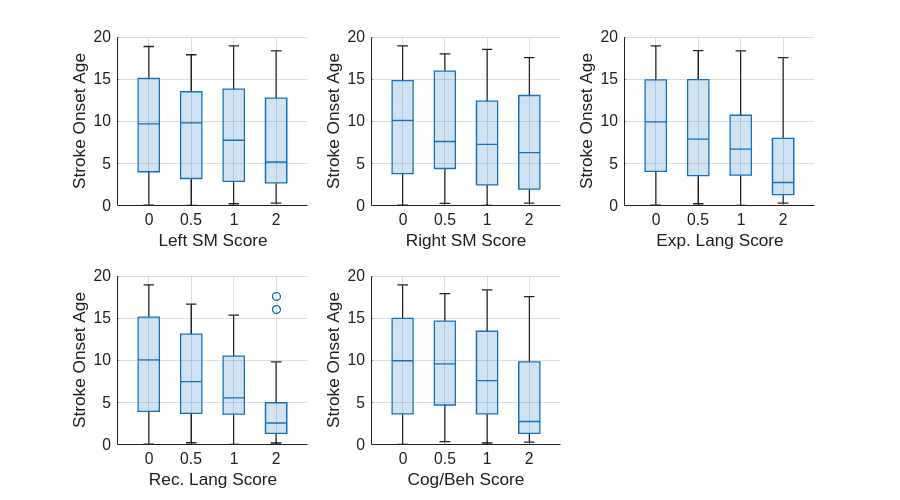

for i = 1:length(my_names)
    nexttile;
    boxchart(categorical(beh_csv.(domains{i})), beh_csv.stroke_age);
    grid on; ylabel('Stroke Onset Age');
    xlabel([my_names{i} ' Score']);
    set(gca, 'FontSize', 12);
end
set(gcf, 'position', [0, 0, 900, 500]);

% Fit single variable (age) and multivariable models for each domain and do model comparisons with BIC

% Standardize predictors
beh_csv.stroke_age = zscore(beh_csv.stroke_age);
beh_csv.yrs2test = zscore(beh_csv.yrs2test);
beh_csv.lh_vol = zscore(beh_csv.lh_vol);
beh_csv.rh_vol = zscore(beh_csv.rh_vol);

% Loop over outcomes, fit models, and do model selection with BIC
domains = {'Left', 'Right', 'Verbal', 'LanguageReception','Cognitive_Behavioral'};
names = {'lmotor', 'rmotor', 'explang', 'reclang', 'cogbeh'};
my_names = {'Left SM', 'Right SM', 'Exp. Lang', 'Rec. Lang', 'Cog/Beh'}

my_names = 1×5 cell array
    {'Left SM'}    {'Right SM'}    {'Exp. Lang'}    {'Rec. Lang'}    {'Cog/Beh'}


coeff_age = zeros(length(domains), 1);
age_ci = zeros(length(domains), 2);
for i = 1:length(domains)

    % Recode outcome
    Y = zeros(length(beh_csv.(domains{i})),1);
    Y(beh_csv.(domains{i}) == 2) = 0;
    Y(beh_csv.(domains{i}) == 1) = 1;
    Y(beh_csv.(domains{i}) == 0.5) = 2;
    Y(beh_csv.(domains{i}) == 0) = 3;    
    beh_csv.(names{i}) = Y;

    % Age only
    mdl_age.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age'], 'ModelType', 'ordinal');
    coeff_age(i,1) = exp(mdl_age.(names{i}).Coefficients.Value(4));
    coeff_ci = coefCI(mdl_age.(names{i}));
    age_ci(i,:) = exp(coeff_ci(4,:));

    % Fit candidate models
    mdl1.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age + yrs2test + lh_vol + rh_vol + lh_vol*stroke_age + rh_vol*stroke_age'], 'ModelType','ordinal');
    mdl2.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age + yrs2test + lh_vol + rh_vol + lh_vol*stroke_age'], 'ModelType','ordinal');    
    mdl3.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age + yrs2test + lh_vol + rh_vol + rh_vol*stroke_age'], 'ModelType','ordinal');    
    mdl4.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age + yrs2test + lh_vol + rh_vol'], 'ModelType','ordinal');    
    mdl_arr = {mdl1.(names{i}), mdl2.(names{i}), mdl3.(names{i}), mdl4.(names{i})};

    % Get and compare BICs
    BIC(i,:) = [mdl1.(names{i}).ModelCriterion.BIC mdl2.(names{i}).ModelCriterion.BIC mdl3.(names{i}).ModelCriterion.BIC mdl4.(names{i}).ModelCriterion.BIC];    
    [~, mdl_ind(i)] = min(BIC(i,:));
    mdl.(names{i}) = mdl_arr{mdl_ind(i)};

end

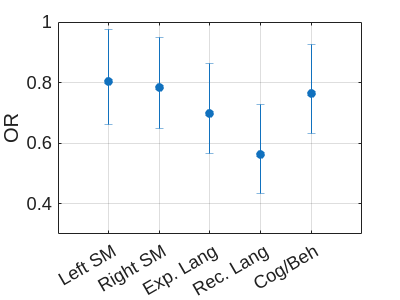

% Plot cumulative ORs and 95% CIs for age
clf;
errorbar(1:1:length(names), coeff_age, coeff_age-age_ci(:,1), age_ci(:,2)-coeff_age, 'LineStyle', 'None', 'Marker', '.', 'MarkerSize', 20);
set(gca, 'Xtick', 1:1:5); set(gca, 'XtickLabel', my_names); axis([0, 6, 0.3, 1]); grid on; set(gca, 'FontSize', 14);
ylabel('OR');set(gcf, 'position', [0, 0, 400, 300]);

% Plot BIC results
clf;
tiledlayout(2,3);
my_names = {'Left SM', 'Right SM', 'Exp. Lang', 'Rec. Lang', 'Cog/Beh'}

my_names = 1×5 cell array
    {'Left SM'}    {'Right SM'}    {'Exp. Lang'}    {'Rec. Lang'}    {'Cog/Beh'}


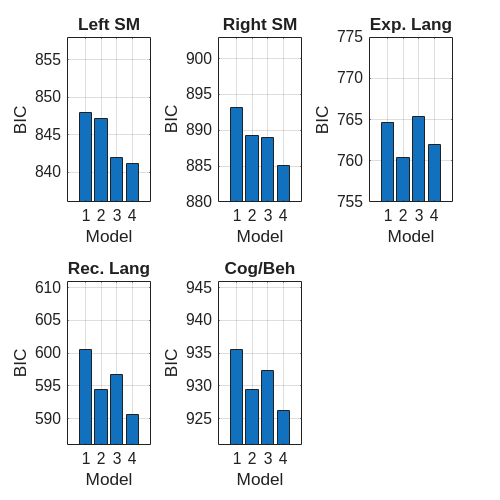

for i = 1:length(my_names)
    nexttile;
    bar(BIC(i,:));
    ylim([round(min(BIC(i,:))-5), round(max(BIC(i,:))+10)]);
    xlabel('Model');
    ylabel('BIC');
    grid on;
    title(my_names{i});
    set(gca, 'Fontsize', 12)
end
set(gcf, 'position', [0, 0, 500, 500]);

% Plot models

for i = 1:length(names)
    
    % Show model table
    disp(['Multivariable model results: ' my_names{i}]);

    % Get coeffs and 95% CIs
    coeffs = exp(mdl.(names{i}).Coefficients.Value(4:end));
    coeff_ci = coefCI(mdl.(names{i})); 
    coeff_ci = coeff_ci(4:end,:); coeff_ci = exp(coeff_ci);
    xnames = replace(mdl.(names{i}).CoefficientNames(4:end), '_', ' ');
    xnames = replace(xnames, 'yrs2test', 'years to test');
    xnames = replace(xnames, ':', ' X ');
    xnames = upper(xnames);

    my_t.(names{i}) = table();
    my_t.(names{i}).Predictors = xnames;
    my_t.(names{i}).coeffs = mdl.(names{i}).Coefficients.Value(4:end);
    my_t.(names{i}).aOR = exp(my_t.(names{i}).coeffs);
    my_t.(names{i}).CIl = coeff_ci(:,1);
    my_t.(names{i}).CIu = coeff_ci(:,2);
    my_t.(names{i}).tstat = mdl.(names{i}).Coefficients.tStat(4:end);
    my_t.(names{i}).pval = mdl.(names{i}).Coefficients.pValue(4:end);
    disp(my_t.(names{i}));
end

Multivariable model results: Left SM


      Predictors        coeffs        aOR        CIl       CIu       tstat        pval   
    _______________    _________    _______    _______    ______    ________    _________

    "STROKE AGE"       -0.087654    0.91608    0.74225    1.1306    -0.81716      0.41384
    "YEARS TO TEST"      0.15495     1.1676    0.95862    1.4221      1.5413      0.12325
    "LH VOL"            -0.47971    0.61896     0.4391    0.8725      -2.741    0.0061252
    "RH VOL"             0.75281      2.123     1.7028    2.6467      6.6968     2.13e-11



Multivariable model results: Right SM


      Predictors        coeffs       aOR        CIl       CIu       tstat        pval   
    _______________    ________    _______    _______    ______    _______    __________

    "STROKE AGE"        -0.1949    0.82292    0.67154    1.0084    -1.8807      0.060013
    "YEARS TO TEST"    0.019075     1.0193    0.83678    1.2415    0.18968       0.84956
    "LH VOL"            0.83879     2.3136     1.8895    2.8328     8.1263    4.4259e-16
    "RH VOL"           -0.14716    0.86316    0.69707    1.0688    -1.3507       0.17679



Multivariable model results: Exp. Lang


         Predictors          coeffs       aOR        CIl        CIu       tstat        pval   
    _____________________    _______    _______    _______    _______    _______    __________

    "STROKE AGE"              -0.285    0.75201    0.59657    0.94796    -2.4144      0.015761
    "YEARS TO TEST"          0.15781     1.1709    0.95063     1.4423     1.4852       0.13749
    "LH VOL"                 0.69673     2.0072     1.6453     2.4487     6.8737    6.2541e-12
    "RH VOL"                  0.3427     1.4087     1.1709     1.6949     3.6358    0.00027715
    "STROKE AGE X LH VOL"    0.27563     1.3174     1.0845     1.6003     2.7792     0.0054496



Multivariable model results: Rec. Lang


      Predictors        coeffs       aOR        CIl        CIu       tstat        pval   
    _______________    ________    _______    _______    _______    _______    __________

    "STROKE AGE"       -0.49164    0.61162    0.46555    0.80353     -3.534    0.00040936
    "YEARS TO TEST"    0.069911     1.0724    0.84286     1.3645    0.56938        0.5691
    "LH VOL"            0.51378     1.6716     1.3823     2.0214     5.3046     1.129e-07
    "RH VOL"            0.24107     1.2726     1.0489      1.544     2.4466      0.014419



Multivariable model results: Cog/Beh


      Predictors        coeffs       aOR        CIl       CIu       tstat        pval   
    _______________    ________    _______    _______    ______    _______    __________

    "STROKE AGE"       -0.14638    0.86383    0.70852    1.0532    -1.4488       0.14739
    "YEARS TO TEST"     0.20528     1.2279     1.0195    1.4788     2.1655       0.03035
    "LH VOL"            0.32754     1.3875     1.1668    1.6501     3.7077    0.00020913
    "RH VOL"            0.30086      1.351     1.1321    1.6122     3.3387    0.00084159



% Conditional effects for Expressive Language

% Z-values and labels for age levels
z_vals = [-1.5,-1, 0, 1];
xlabels = {'~3.5m', '~3y', '~9y', '~15y'};

% Expressive lang
clf;
run_cfx_analysis(mdl2.explang, 6, 8, z_vals, xlabels, 'r'); 

Z = -1.50: Slope = 0.2833, SE = 0.1511, p = 0.0608
Z = -1.00: Slope = 0.4211, SE = 0.1171, p = 0.0003
Z = 0.00: Slope = 0.6967, SE = 0.1014, p = 0.0000
Z = 1.00: Slope = 0.9724, SE = 0.1628, p = 0.0000


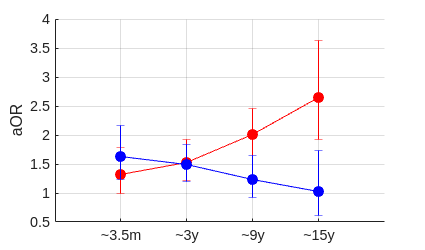

Z = -1.50: Slope = 0.4907, SE = 0.1444, p = 0.0007
Z = -1.00: Slope = 0.3986, SE = 0.1077, p = 0.0002
Z = 0.00: Slope = 0.2144, SE = 0.1476, p = 0.1465
Z = 1.00: Slope = 0.0301, SE = 0.2651, p = 0.9095


hold on; 
run_cfx_analysis(mdl1.explang, 7, 9, z_vals, xlabels, 'b');

% Post-hoc analyses of Receptive Language

% Z-values and labels for age levels
z_vals = [-1.5,-1, 0, 1];
xlabels = {'~3.5m', '~3y', '~9y', '~15y'};

% Expressive lang
clf;
run_cfx_analysis(mdl1.reclang, 6, 8, z_vals, xlabels, 'r'); 

Z = -1.50: Slope = 0.3069, SE = 0.1544, p = 0.0469
Z = -1.00: Slope = 0.3883, SE = 0.1191, p = 0.0011
Z = 0.00: Slope = 0.5511, SE = 0.1016, p = 0.0000
Z = 1.00: Slope = 0.7139, SE = 0.1646, p = 0.0000


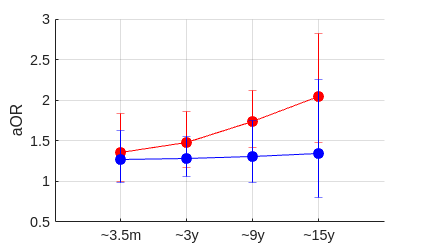

Z = -1.50: Slope = 0.2359, SE = 0.1294, p = 0.0683
Z = -1.00: Slope = 0.2479, SE = 0.0989, p = 0.0122
Z = 0.00: Slope = 0.2718, SE = 0.1482, p = 0.0668
Z = 1.00: Slope = 0.2957, SE = 0.2627, p = 0.2604


hold on; 
run_cfx_analysis(mdl1.reclang, 7, 9, z_vals, xlabels, 'b');